%Exercise 1.1
load('TRC_display.mat');

disp('Exercise 1.1');

Exercise 1.1


disp('Plot TRC')

Plot TRC


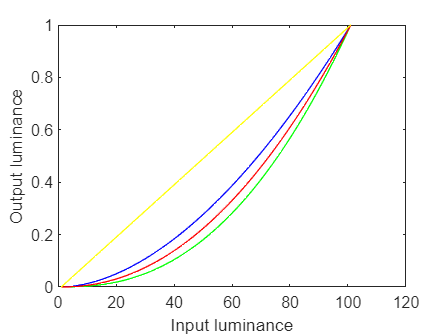


%TRC - tone reproduction curves
plot(TRCb, 'b');
hold on
plot(TRCg,'g');
hold on
plot(TRCr, 'r');
linear = 0:0.01:1;
hold on
xlabel('Input luminance');
ylabel('Output luminance');
plot(linear,'y');

%Exercise 1.2
load('Ramp_display.mat');
load('Ramp_linear.mat');

disp('Exercise 1.2');

Exercise 1.2


disp('Linearize ramp using interpolation')

Linearize ramp using interpolation


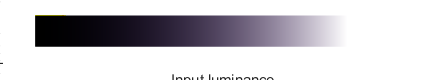


%Ramp - Image of neutral ramp displayed without calibration
imshow(Ramp_display)

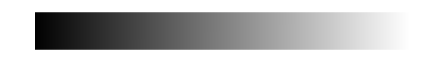

imshow(Ramp_linear)

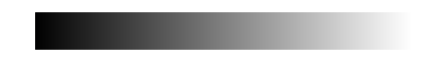


TRCMatrix(:,:,1) = TRCr;
TRCMatrix(:,:,2) = TRCg;
TRCMatrix(:,:,3) = TRCb;

%Linearize Ramp
linearized_img = Linearize(TRCMatrix,Ramp_display);

imshow(linearized_img);

%Exercise 1.3
disp('Exercise 1.3');

Exercise 1.3


disp('Linearize ramp using gamma correction')

Linearize ramp using gamma correction


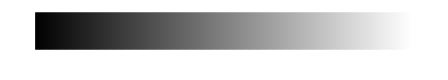

%Equation 4: Dr = Dmax(D'R/Dmax)^(1/yr)
%CRT - Cathode Ray Tube

yr = 2.1;
yg = 2.4;
yb = 1.8;

%Since pixelvalues - 0:1
Dmax = 1;

%Gamma correction for each channel
D(:,:,1) = Dmax.*(Ramp_display(:,:,1).^(1/yr));
D(:,:,2) = Dmax.*(Ramp_display(:,:,2).^(1/yg));
D(:,:,3) = Dmax.*(Ramp_display(:,:,3).^(1/yb));

imshow(D);

%Exercise 2.1
load('DLP.mat');

disp('Exercise 2.1');

Exercise 2.1


disp('Plot spectra for the projector')

Plot spectra for the projector


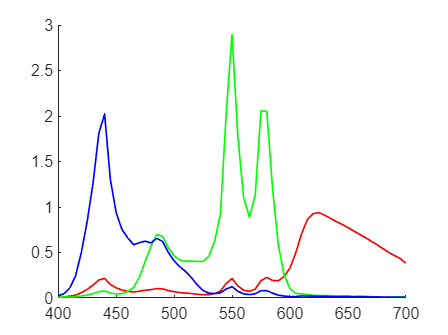

%DLP projector - uses DMD technology
%DMD - controls amount of light by alter the time and not power
%Output is linear in luminance

%Equation 1: Srmax + Sgmax + Sbmax = Srgb

%DLP- Spectral data for the r,g and b channels
x = 400:5:700;

figure;
%Plot the channels
hold on
plot(x, DLP(:, 1), 'r', 'LineWidth', 1); % R 
plot(x, DLP(:, 2), 'g', 'LineWidth', 1); % G 
plot(x, DLP(:, 3), 'b', 'LineWidth', 1); % B
hold off

%Exercise 2.2
%Equation 2: Dr'Srmax + Dg'Sgmax + Db'Sbmax = Srgb -> emitted spectral
%radiance

load('RGB_raw.mat');
load('DLP.mat');
load('illum.mat');
load("xyz.mat");
load('XYZ_ref.mat');


disp('Exercise 2.2');

Exercise 2.2


disp('XYZ-values for the projector and color difference')

XYZ-values for the projector and color difference


disp('with CIED65 and RGB_raw as input')

with CIED65 and RGB_raw as input



%Find SRGB for all twenty objects
%RGB-raw: Camera from lab1 as input for projector
SRGB = DLP*RGB_raw;

%Calculate the normalization factor under CIED65 illumination
%From lab1
k = 100./(CIED65*xyz(:,2));

%Convert the spectral radiance to XYZ-values (as in lab1)
XYZ_SRGBD65 = xyz'*SRGB .* k;

%Convert the XYZ for the projector to Lab
[L1,a1,b1] = xyz2lab(XYZ_SRGBD65(1,:)', XYZ_SRGBD65(2,:)', XYZ_SRGBD65(3,:)');

%Convert XYZ_ref to Lab
[L2,a2,b2] = xyz2lab(XYZ_ref(1,:)',XYZ_ref(2,:)',XYZ_ref(3,:)');

%Calculate the color difference
diff = sqrt((L1 - L2).^2 + (a1 - a2).^2 + (b1 - b2).^2);

%Find the mean and max value in color difference
diffMean = mean(diff);
diffMax = max(diff);

disp("Color difference mean-value: " + diffMean)

Color difference mean-value: 22.3508


disp("Color difference max-value: "+ diffMax)

Color difference max-value: 51.638


%Exercise 2.3
disp('Exercise 2.3');

Exercise 2.3


disp('XYZ-values for the projector and color difference')

XYZ-values for the projector and color difference


disp('with CIED65 and RGB_cal as input')

with CIED65 and RGB_cal as input




load('RGB_cal.mat');
load('DLP.mat');
load('illum.mat');
load("xyz.mat");
load('XYZ_ref.mat');

%Find SRGB for all twenty objects
SRGB = DLP*RGB_cal;

%Calculate the normalization factor under CIED65 illumination
%From lab1
k = 100./(CIED65*xyz(:,2));

%Convert the spectral radiance to XYZ-values (as in lab1)
XYZ_SRGBD65 = xyz'*SRGB .* k;

[L1,a1,b1] = xyz2lab(XYZ_SRGBD65(1,:)', XYZ_SRGBD65(2,:)', XYZ_SRGBD65(3,:)');

%Convert XYZ_ref to Lab
[L2,a2,b2] = xyz2lab(XYZ_ref(1,:)',XYZ_ref(2,:)',XYZ_ref(3,:)');

%Calculate the color difference
diff = sqrt((L1 - L2).^2 + (a1 - a2).^2 + (b1 - b2).^2);

%Find the mean and max value in color difference
diffMean = mean(diff);
diffMax = max(diff);

disp("Color difference mean-value: " + diffMean)

Color difference mean-value: 16.9236


disp("Color difference max-value: "+ diffMax)

Color difference max-value: 33.5351


%Exercise 3.1

disp('Exercise 3.1');

Exercise 3.1


disp('Calculate Acrt matrix')

Calculate Acrt matrix



%Normalization factor
k = 100./(CIED65*xyz(:,2));

%Tristumulus values for the conversion matrix (XYZ) 
Acrt = xyz'*DLP*k;


%Exercise 3.2
disp('Exercise 3.2');

Exercise 3.2


disp('XYZ with input and output device');

XYZ with input and output device


disp('Input: XYZ_D65_ref from lab1');

Input: XYZ_D65_ref from lab1


disp('Output: Acrt')

Output: Acrt



%Matrices from lab1, 3.4 and 3.5
load('estimate.mat'); 
load('XYZ_D65_ref.mat');

%%Convert to XYZ-values
%Inverse to determine device dependent values (D'r ...)
%for device independent target colors (in XYZ)
%Inverse function as in lab1
A_inv = inv(Acrt)*estimate;
XYZ_SRGB  = xyz'*(DLP*A_inv)*k;

%Convert to Lab for SRGB
[L1, a1, b1] =  xyz2lab(XYZ_SRGB(1,:)', XYZ_SRGB(2,:)', XYZ_SRGB(3,:)');

%Convert to Lab for XYZ_D65_ref
[L2, a2, b2] =  xyz2lab(XYZ_D65_ref(1,:)', XYZ_D65_ref(2,:)', XYZ_D65_ref(3,:)');

%Calculate color difference
diff = sqrt((L1 - L2).^2 + (a1 - a2).^2 + (b1 - b2).^2);

diffMean = mean(diff);
diffMax = max(diff);

disp("Color difference mean-value: " + diffMean)

Color difference mean-value: 1.0238


disp("Color difference max-value: "+ diffMax)

Color difference max-value: 3.1053


%Exercise 3.3
disp('Exercise 3.3');

Exercise 3.3


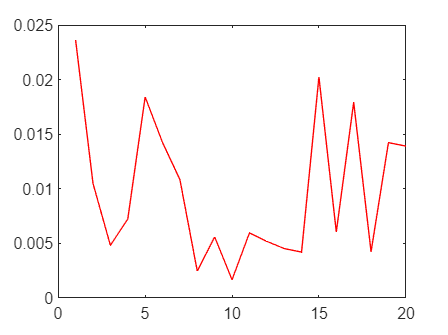

figure;

plot(SRGB(1,:),'r');

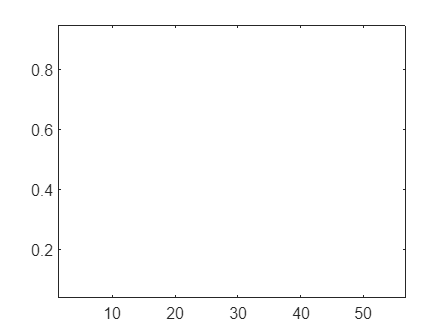

plot(DLP(:,1),'r');

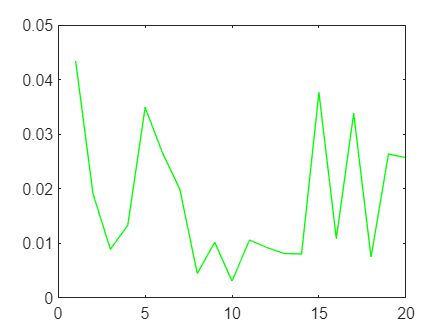



plot(SRGB(2,:),'g');

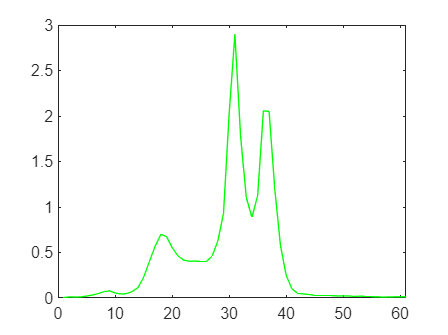

plot(DLP(:,2),'g');

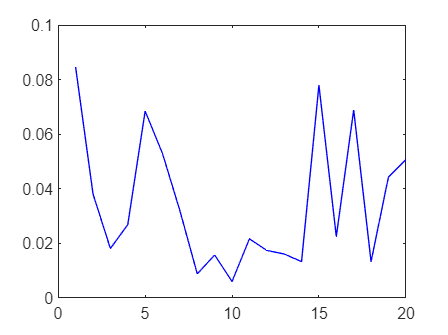



plot(SRGB(3,:),'b');

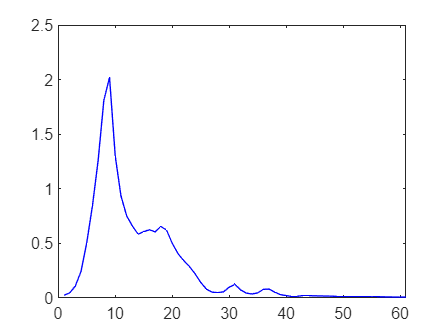

plot(DLP(:,3),'b');

%Exercise 3.4
disp('Exercise 3.4');

Exercise 3.4


disp('Modify XYZ_SRGB to lie between 0 and 1')

Modify XYZ_SRGB to lie between 0 and 1





%Modifie values in conversion matrix to 0:1
for i = 1:numel(A_inv)  % Loopar genom alla element
    if A_inv(i) > 1
        A_inv(i) = 1;
    elseif A_inv(i) < 0
        A_inv(i) = 0;
    end
end
XYZ_SRGB_2  = (xyz'*(DLP*A_inv))*k;

%Convert to Lab
[L1, a1, b1] =  xyz2lab(XYZ_SRGB_2(1,:)', XYZ_SRGB_2(2,:)', XYZ_SRGB_2(3,:)');
[L2, a2, b2] =  xyz2lab(XYZ_D65_ref(1,:)', XYZ_D65_ref(2,:)', XYZ_D65_ref(3,:)');

%Calculate color difference
diff3 = sqrt((L1 - L2).^2 + (a1 - a2).^2 + (b1 - b2).^2);

diffMean3 = mean(diff3);
diffMax3= max(diff3);

disp("Color difference mean-value: " + diffMean3)

Color difference mean-value: 2.836


disp("Color difference max-value: "+ diffMax3)

Color difference max-value: 17.874


%Exercise 3.5
disp('Exercise 3.5')

Exercise 3.5


disp('Chromacity coordinates')

Chromacity coordinates


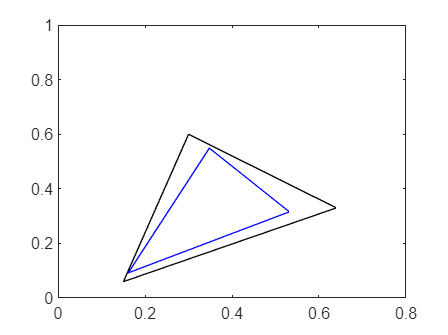


%Acrt - blue
%sRGB - black
plot_chrom_sRGB(Acrt)

%Exercise 3.6
load('chips20.mat');
load('illum.mat');
load('xyz.mat');
load('XYZ_D65_ref.mat');
load('DLP.mat');

disp('Exercise 3.6')

Exercise 3.6



k = 100./(CIED65*xyz(:,2));

ref = XYZ_D65_ref(:,1);

est = XYZ_SRGB_2(:,1);

[L1, a1, b1] =  xyz2lab(est(1,:)', est(2,:)', est(3,:)');

[L2, a2, b2] =  xyz2lab(ref(1,:)', ref(2,:)', ref(3,:)');


diff = sqrt((L2-L1).^2+(a2-a1).^2+(b2-b1).^2);

disp("Color difference: " + diff);

Color difference: 0.033663


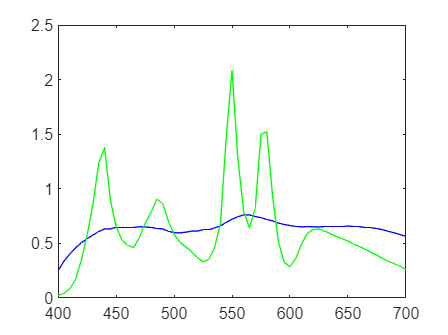




x = 400:5:700;
chips = chips20(1,:).*CIED65;
plot(x, chips, 'blue');
hold on
plot(x,SRGB(:,1), 'green')
hold off